# TD MSD3 2019-20

## Exo 9. Prestressed concrete

**1) Tensile behaviour of reinforced concrete **

Reinforced concrete is used for construction of buildings or structures. It represents the most used composite material. Concrete is a low cost material that exhibit a high compression resistance, but with a low tensile resistance (1/10 of the compression). Associated with steel it exhibits a higher tensile resistance. Concrete is poured in the liquid state around steel bars, then it solidifies before gaining the final properties.

We consider a cylindrical sample of reinforced concrete after hardening of the concrete (see figure below). The total diameter of the sample is $d_1$ and that of the central steel bar is $d_2$. 

A load $F$ is applied to the sample along the sample axis, direction 1. 

**1.1 **  Calculate the stresses in the steel and in the concrete. For that question, neglect the Poisson’ effects and only consider direction 1. 

 **1.1 **This is a case of pure tension since we neglect the Poisson's effect between the concrete and the steel. Let's consider the axis $x_1$ along the loading direction. Thefore to simplify one can write $\sigma_{11}^c=\sigma_c$ and $\sigma_{11}^s=\sigma_s$. We have the Young's equations :

    
$$\left\{\begin{array}{cc}\epsilon_c=\frac{\sigma_c}{E_c}\\ \epsilon_s=\frac{\sigma_s}{E_s}\end{array}$$


Since the boundary between the steel and the concrete is perfect, $\epsilon_s=\epsilon_c$

Furthermore, the static equilibrium equation applies : $F=\sigma_cS_c +\sigma_s S_s$  with $S_s =\frac{\pi {d_2 }^2 }{4}$  and $S_c =\frac{\pi \left({d_1 }^2 -{d_2 }^2 \right)}{4}$ 

clear all
syms ss sc F Ss Sc Es Ec
A1=sc/Ec-ss/Es;
A2=F-ss*Ss-sc*Sc;
[A B]=equationsToMatrix([A1,A2],[ss,sc])

$$A = \left(\begin{array}{cc} -\frac{1}{\mathrm{Es}} & \frac{1}{\mathrm{Ec}}\\ -\mathrm{Ss} & -\mathrm{Sc} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ -F \end{array}\right)$$

sol=inv(A)*B

$$sol = \left(\begin{array}{c} \frac{\mathrm{Es}\,F}{\mathrm{Ec}\,\mathrm{Sc}+\mathrm{Es}\,\mathrm{Ss}}\\ \frac{\mathrm{Ec}\,F}{\mathrm{Ec}\,\mathrm{Sc}+\mathrm{Es}\,\mathrm{Ss}} \end{array}\right)$$

Es=210e3; Ec=30e3; d1=40; d2=16; Ss=pi*d2^2/4; Sc=pi*(d1^2-d2^2)/4; F=10e3;
ss=eval(sol(1)); fprintf('sig_s = %1.2f MPa',ss)

sig_s = 28.42 MPa

sc=eval(sol(2)); fprintf('sig_c = %1.2f MPa',sc)

sig_c = 4.06 MPa

**1.2 **  Calculate the safety coefficient in the concrete, defined as the ratio between the strength (in tension or compression) over the applied stress on the material during service. What does this coefficient represent ? 

The stresses are positive, i.e. tensile stresses, so one must compare the stress values to the tensile strength for both materials. 

 ${Saf}_s =\frac{\sigma_s }{Rt_s}$ and ${Saf}_c =\frac{s_c }{Rt_c}$ 

Rta=1500;Rtc=3.5;
Safc=sc/Rtc; fprintf('Saf_c = %1.2f',Safc)

Saf_c = 1.16

So the safety coefficient is overpassed, which means that the concrete might be damaged and should not be used under these circumstances.

**2°) Prestressed concrete**

Prestressed concrete has been invented by Eugène Freyssinet in 1928, in order to build beams, bridges or floor of larger span that can be made with reinforced concrete. The process to make such prestressed concrete is described by the following steps.

(i) The steel bar of initial length $L_0$ is submitted to a tensile load $P$ inducing a length increase to $L_1$. 

(ii) While the bar is maintained in this tensile state, the concrete is poured around, it hardens until it reaches its mechanical properties described above. 

(iii) The load applied on the steel bar is further released. We assume the interface between the steel bar and concrete is perfect, which means that the shape of the sample doesn’t vary after the unloading. 

**2.1 Calculation of the residual stresses in the prestressed concrete. **

**2.1.1** Find the stress and strain tensors induced in the steel bar during the step (i), expressed in the axis system (1, 2, 3). 

    Tensile stress state : $\bar\bar\sigma_s =\left\lbrack \begin{array}{ccc}\frac{P}{S_s } & 0 & 0\\0 & 0 & 0\\0 & 0 & \end{array}\right\rbrack$ and $\bar\bar\epsilon_s =\left\lbrack \begin{array}{ccc}\epsilon_1^s & 0 & 0\\0 & \epsilon_2^s & 0\\0 & 0 &\epsilon_2^s \end{array}\right\rbrack$ with $\epsilon_1^s=\frac{P}{S_sE_s}$ and $\epsilon_2^s=-\nu\frac{P}{S_sE_s}$

P=8000; nu =0.3;
ss1=P/Ss; fprintf('ss1 = %1.1f MPa',ss1)

ss1 = 39.8 MPa

es1=ss1/Es; fprintf('es1 = %1.1e',es1)

es1 = 1.9e-04

es2=-nu*es1;  fprintf('es2 = %1.1e',es2)

es2 = -5.7e-05

**2.1.2**  Represent the different steps (i), (ii) and (iii) on a schematic drawing with the useful variables. Deduce the sign of the residual stresses in concrete and steel after release of the load. 

The steal is in blue on the figure. We apply the load $P$ on the steal bar that exhibits the length $L_1$, the concrete is pourred around the steal and is free of stress at this stage. We release the load $P$. The steal "tends" to recover its initial free equilibrium length $L_0$ while the concrete "tends" to keep its free equilibrium length $L_1$. They therefore exhibit the intermediate length $L_f$.

    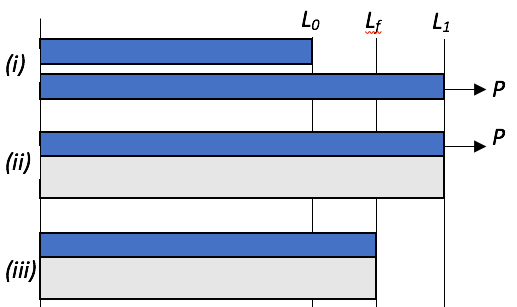

Therefore the steal has a final length larger than the equilibrium one, it is in tension, while the concrete exhibiting a smaller length than the equilibrium is in compression.

**2.1.3** Express the residual strains in steel and concrete after step (iii) as function of the different lengths : $L_0$  length of the unstresed steel bar, $L_1$ length after applying the prestressing load and $L_f$ at the end of the process.

The definition of the residual strain is the final length minus the equilibrium length, over the equilibrium length, which gives for steel and concrete: $\varepsilon_s^{\mathrm{res}} =\frac{L_f -L_0 }{L_0 }$   and $\varepsilon_c^{\mathrm{res}} =\frac{L_f -L_1 }{L_1 }$ 

**2.1.4** Write the different equations allowing the calculation of the stresses and calculate these residual stresses. 

The different equations are    

- Equlibrium equation of the final system under nil external load :     $\sigma_s^{\mathrm{res}} S_s +\sigma_c^{\mathrm{res}} S_c =0$ (2)

- Young relation in the steel :       $\epsilon_s^{\mathrm{res}} =\frac{\sigma_s^{\mathrm{res}} }{E_s }$   (3)

- Young relation in the concrete : $\epsilon_c^{\mathrm{res}} =\frac{\sigma_c^{\mathrm{res}} }{E_c }$  (4)

- Description of the steel under the load $P$ :      $\frac{L_1 -L_0 }{L_0 }=\frac{P}{E_s S_s }$    (1)  

In order to solve the system one must eliminate the different length $L_0$, $L_f$ and $L_1$ since the final stress state does not depend on these quantities, it only depends on the Young's modulii, the cross-section areas and on the load $P$. This would lead us to four unknowns $\sigma_s^{res}$, $\sigma_c^{res}$, $\epsilon_s^{res}$ and $\epsilon_c^{res}$.

One can rearrange the expressions of the residual strains to eliminate $L_f$  as : 

    $\left\{\begin{array}{cc}(\epsilon_s^{res}+1)L_0=L_f\\ (\epsilon_c^{res}+1)L_1=L_f \end{array}$   $\iff \frac{\varepsilon_s^{\mathrm{res}} +1}{\varepsilon_c^{\mathrm{res}} +1}=\frac{L_1 }{L_0 }$  (5)

One can rewrite eqn(1) as :  $\frac{L_1 -L_0 }{L_0 }=\frac{P}{E_s S_s }\iff \frac{L_1}{L_0}=\frac{P}{E_s S_s }+1$ and combine the result to eqn(5) to eliminate the ratio $\frac{L_1}{L_0}$ leading to 

    $\left(\frac{P}{E_s S_s }+1\right) \left(\varepsilon_c^{\mathrm{res}} +1\right)=\varepsilon_s^{\mathrm{res}} +1$     (6)

Considering equation (6), (2), (3) and (4) leads to the following system with 4 equations with 4 unknowns :

    
$$\left\{\begin{array}{ccc} \left(\frac{P}{E_s S_s }+1\right) \left(\varepsilon_c^{\mathrm{res}} +1\right)=\varepsilon_s^{\mathrm{res}} +1\\ \sigma_s^{\mathrm{res}} S_s +\sigma_c^{\mathrm{res}} S_c =0 \\ \epsilon_s^{\mathrm{res}} =\frac{\sigma_s^{\mathrm{res}} }{E_s } \\ \epsilon_c^{\mathrm{res}} =\frac{\sigma_c^{\mathrm{res}} }{E_c }\end{array}$$


That can be solved using Matlab :

clear all
syms ss sc es ec Es Ec Ss Sc P
A6=(P/Es/Ss+1)*(ec+1)-(es+1);
A2=ss*Ss+sc*Sc;
A3=es-ss/Es;
A4=ec-sc/Ec;
[A B]=equationsToMatrix([A6,A2,A3,A4],[ss,sc,es,ec]);
sol=inv(A)*B;

Let's write the analytical expressions of the residual stresses :

sig_s=sol(1)

$$sig\_s = \frac{\mathrm{Ec}\,P\,\mathrm{Sc}}{\mathrm{Ss}\,\left(P+\mathrm{Ec}\,\mathrm{Sc}+\mathrm{Es}\,\mathrm{Ss}\right)}$$

sig_c=sol(2)

$$sig\_c = -\frac{\mathrm{Ec}\,P}{P+\mathrm{Ec}\,\mathrm{Sc}+\mathrm{Es}\,\mathrm{Ss}}$$

The numerical results are : 

Es=210e3; Ec=30e3; d1=40; d2=16; Ss=pi*d2^2/4; Sc=pi*(d1^2-d2^2)/4; F=10e3; P=8e3;
sig_s_res=eval(sig_s); fprintf('sig_s_res = %1.2f MPa',sig_s_res) 

sig_s_res = 17.05 MPa

sig_c_res=eval(sig_c); fprintf('sig_c_res = %1.2f MPa',sig_c_res) 

sig_c_res = -3.25 MPa

We indeed find, as expected a compressive stress in the concrete material.

**2.2 Tensile behaviour of the prestressed concrete**

A load $F$, equal to that in question 1 is applied to the pre-stressed concrete. 

Calculate the stress state in both materials and calculate the new value of the safety factor (use definition given in 1.2).  Compare to the results obtained in question 1 and explained the interest of prestressed concrete.

Adding a load $F$ to the pre-stressed concrete means adding two stress states : the residual stress state and the stress state induced by $F$. We therefore just have to add both stresses for both materials, which leads to :

    $\sigma_s^{tot}=\sigma_s^{res}+\sigma_s$  and $\sigma_c^{tot}=\sigma_c^{res}+\sigma_c$

the stresses values found in question (1) where : 

sig_s=28.99; sig_c=3.95;
sig_s_tot=sig_s_res+sig_s; fprintf('sig_s_tot = %1.2f MPa',sig_s_tot)

sig_s_tot = 46.04 MPa

sig_c_tot=sig_c_res+sig_c; fprintf('sig_c_tot = %1.2f MPa',sig_c_tot)

sig_c_tot = 0.70 MPa

This time the total stres in the concrete is lower than its maximum tensile strenght, and it should not be damaged.

 **Numerical data:**

*d**1* = 40 mm, *d**2* = 16 mm, *F*= 10 000 N, *P* = 8 000 N

Concrete : *E**b* = 30 GPa, tensile strength *Rt**b* = 3,5 MPa, compression strength *Rc**b* = 35 MPa

Steel : *E**a* = 220 GPa, tensile strength *Rta* = 1500 MPa, compression strength* Rc**a* = 1700 MPa